**Modeling and Optimizing A Battery Charging Profile**

*Modeling Battery Voltage Versus Time *

    The first graph simulates a charging model of a Lithium Ion battery using V(t)=Vmax(1-e^-t/RC). This equation models the charging of an RC battery, and is graphed as shown.

    Change the sliders below or enter a value to simulate how different capacitances, resistances, and max voltages change the Voltage vs. TIme charging graph!

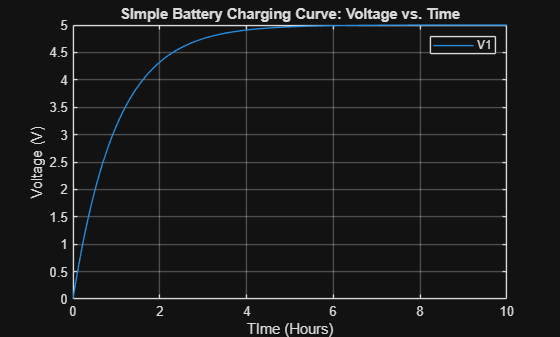

Vmax1 = 5;    
R1 = 1;       
C1 = 1;       
t1 = linspace(0, 10, 1000);  
V1 = Vmax1 * (1 - exp(-t1 / (R1 * C1)));

figure;
clf;
h4 = plot(t1,V1,"DisplayName","V1");
legend
grid on
xlabel("TIme (Hours)")
ylabel("Voltage (V)")
title("SImple Battery Charging Curve: Voltage vs. Time")

*Creating a Fitted Voltage Versus Time Graph*

    Battery Specs: LIR18650 2600mAh

    Using a battery data sheet, the graph shown above was fitted to portray the charging model of the battery that was chosen. 

    Use the slider below or enter a value to show the time it takes the selected battery to charge to a certain percentage, as well as where it is located on the graph!

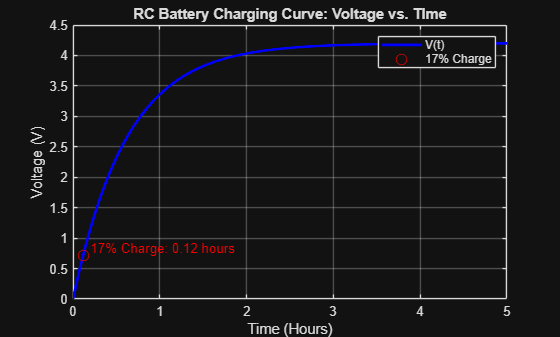

Vmax2 = 4.2;              
R2 = 0.07;                  
RC2 = 2237;               
C2 = RC2 / R2;              

t2 = linspace(0, 18000, 1000); 
V2 = Vmax2 * (1 - exp(-t2 / (R2 * C2)));

desired_pct =17;

if desired_pct <= 0 || desired_pct >= 100
    error('Please enter a charge percentage between 0 and 100 (non-inclusive). Litihium batteries do not charge all the way to 100%.');
end

V_target = Vmax2 * (desired_pct / 100);
t_target = -R2 * C2 * log(1 - (desired_pct / 100));

figure;
plot(t2 / 3600, V2, 'b-', 'LineWidth', 2);  
xlabel('Time (Hours)');
ylabel('Voltage (V)');
title('RC Battery Charging Curve: Voltage vs. TIme');
grid on;
hold on;

plot(t_target / 3600, V_target, 'ro', 'MarkerSize', 8, ...
    'DisplayName', sprintf('%d%% Charge', desired_pct));
text(t_target / 3600, V_target, sprintf('  %d%% Charge: %.2f hours', ...
    desired_pct, t_target / 3600), ...
    'VerticalAlignment', 'bottom', 'Color', 'red');

legend('V(t)', sprintf('%d%% Charge', desired_pct));

*Total Energy Delivered To Battery*

    The next process involves using integration techniques to illustrate how much energy the battery recieves. This is found by calculating the area under the Power vs. Time curve.

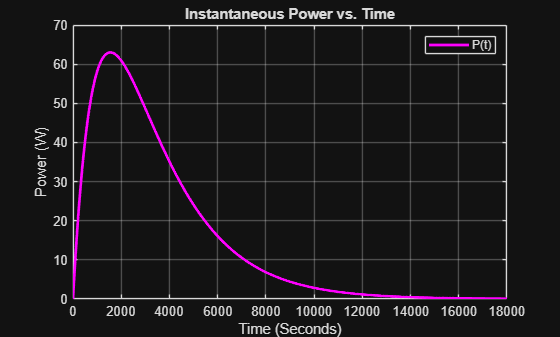

P = @(t) (Vmax2 * (1 - exp(-t / (R2 * C2)))) .* ((Vmax2 / R2) * exp(-t / (R2 * C2)));
t_power = linspace(0, 18000, 1000);
P_vals = P(t_power);

figure;
plot(t_power, P_vals, 'm-', 'LineWidth', 2);
xlabel("Time (Seconds)");
ylabel("Power (W)");
title("Instantaneous Power vs. Time");
grid on;
legend("P(t)");

E = integral(P, 0, 18000);  
fprintf('Total energy delivered to the battery: %.2f joules\n', E);

Total energy delivered to the battery: 281681.51 joules


*Rate of Voltage Change at Different Intervals*

    This graph illustrates the derivative of the Voltage vs. Time graph, and shows how quickly the voltage is increasing or decreasing at a certain time interval. 

    Changing the slider below provides the average change in voltage at the intervals that was changed. 

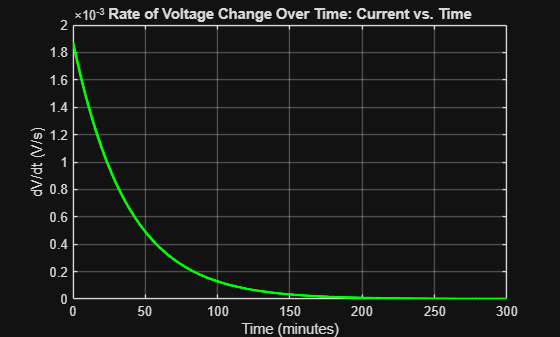

interval_pct = 30;  

Vmax = Vmax2;
R = R2;
C = C2;
t = t2;  

V = Vmax * (1 - exp(-t / (R * C)));
dVdt = gradient(V, t); 

figure;
plot(t / 60, dVdt, 'g', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('dV/dt (V/s)');
title('Rate of Voltage Change Over Time: Current vs. Time');
grid on;


num_intervals = floor(100 / interval_pct);
fprintf('\nAverage dV/dt in %.0f%% intervals:\n', interval_pct);


Average dV/dt in 30% intervals:


for i = 1:num_intervals
    lower_pct = (i-1) * interval_pct;
    upper_pct = i * interval_pct;
    lower_V = Vmax * lower_pct / 100;
    upper_V = Vmax * upper_pct / 100;
    
    mask = (V >= lower_V) & (V < upper_V);
    if any(mask)
        avg_dVdt = mean(dVdt(mask));
    else
        avg_dVdt = NaN;
    end
    
    fprintf('%2.0f%% - %2.0f%% (%.2fV - %.2fV): %.6f V/s\n', ...
        lower_pct, upper_pct, lower_V, upper_V, avg_dVdt);
end

 0% - 30% (0.00V - 1.26V): 0.001581 V/s
30% - 60% (1.26V - 2.52V): 0.001007 V/s
60% - 90% (2.52V - 3.78V): 0.000407 V/s


*Energy Lost Due To Internal Resistance*

    The next section states how much energy in joules, the battery loses due to its internal resistance. Energy can be found by taking the integral of power over a certain time, and our value is 

    found by taking the integral of our Power Lost vs. Time graph over its timespan in seconds.  

T_end = 18000;
RC = 2337;
I = @(t) (Vmax / R) * exp(-t / RC);
P_loss = @(t) (I(t)).^2 * R;
E_loss = integral(P_loss, 0, T_end);

fprintf('\nEnergy lost due to resistance: %.2f joules\n', E_loss);


Energy lost due to resistance: 294461.94 joules



t = linspace(0, T_end, 1000);
P_vals = P_loss(t);

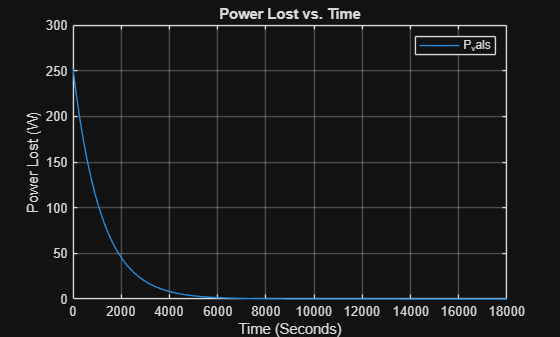

% Create plot of selected data
h7 = plot(t,P_vals,"DisplayName","P_vals");

% Add xlabel, ylabel, title, and legend
xlabel("t")
ylabel("P_vals")
title("P_vals vs. t")
legend
title("Power Lost vs. Time")
grid on
ylabel("Power Lost (W)")
xlabel("Time (Seconds)")

*Optimized Charging With Safety Limits*

    This section opens up further user input to optimize the previous battery charging profile.  

    Change the sliders for Resistance and the TIme Constant (RC0) to see how the charging ccurve changes. Get feedback as to how optimized your values are. 

    (Hint: To optimize battery charging, try setting resistance at around 2 Ohms, and RC0 at around 1000 seconds)

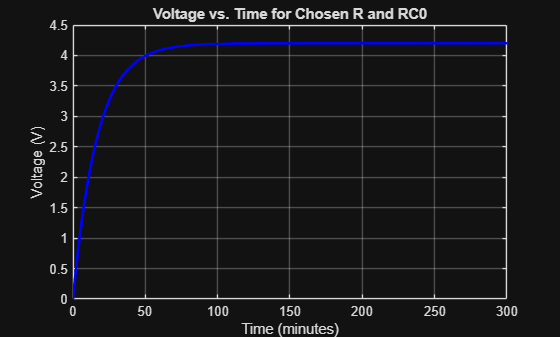

R = 2.1;    
RC0 = 1000;   

Vmax = 4.2;          
C = RC0 / R;         
T_end = 18000;       

t = linspace(0, T_end, 1000);
V = Vmax * (1 - exp(-t / (R * C)));

figure;
plot(t / 60, V, 'b', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Voltage (V)');
title('Voltage vs. Time for Chosen R and RC0');
grid on;


V_target = 0.90 * Vmax;  
I_max = 2.6;              

charging_time = @(RC) -log(1 - V_target / Vmax) * RC;
obj = @(RC) charging_time(RC);

if Vmax / R > I_max
    fprintf('Current exceeds safety limit at t=0: %.2f A > %.2f A\n', Vmax/R, I_max);
    feasible = false;
else
    feasible = true;
end

if feasible
    options = optimoptions('fmincon', 'Display', 'off');
    [RC_opt, T_opt] = fmincon(obj, RC0, [], [], [], [], 1000, 20000, [], options);
    
    fprintf('Optimized RC: %.2f seconds\n', RC_opt);
    fprintf('Time to reach 90%% of Vmax: %.2f seconds (%.2f min)\n', T_opt, T_opt/60);

    user_time = charging_time(RC0);
    efficiency_ratio = T_opt / user_time;
    
    if abs(efficiency_ratio - 1) < 0.05
        fprintf('Your chosen RC (%.0f) is near-optimal for fast charging.\n', RC0);
    elseif efficiency_ratio < 1
        fprintf('Your RC0 is higher than optimal. Try reducing RC0 for faster charging.\n');
    else
        fprintf('Your RC0 is lower than optimal. Try increasing RC0 for better battery protection.\n');
    end
end

Optimized RC: 1000.00 seconds


Time to reach 90% of Vmax: 2302.59 seconds (38.38 min)


Your chosen RC (1000) is near-optimal for fast charging.


*Adding Temperature Constraints and Non-Ideal Behaviour*

    This section of our project incorporates temperature into the battery charging profile, and shows how a temperature difference can inhibit charging, and cause things like thermal runaway.

    Input a temperature (in Celcius) below, which changes the Temperature-Adjusted Charging Curve

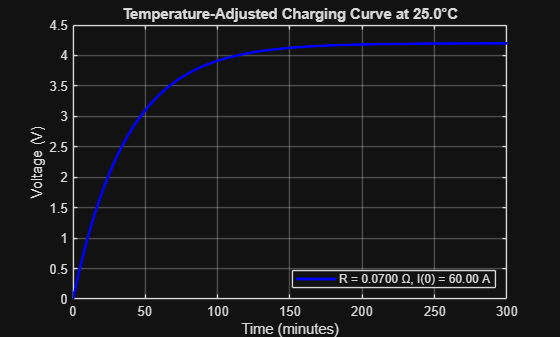

user_temp_C = 25; 

if user_temp_C < 0
    warning('Temperature too low! Battery charging may be unsafe or ineffective.');
elseif user_temp_C > 60
    warning('Temperature too high! Risk of battery degradation or thermal runaway!');
end

R_base = 0.07;    
temp_coeff = 0.004;  

delta_T = user_temp_C - 25;
R_temp = R_base * (1 + temp_coeff * delta_T);

RC0 = 2237;     
C_temp = RC0 / R_temp;

T_end = 18000;   
t = linspace(0, T_end, 1000);

Vmax = 4.2; 
V_temp = Vmax * (1 - exp(-t / (R_temp * C_temp)));

I0_temp = Vmax / R_temp;

figure;
plot(t / 60, V_temp, 'b-', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Voltage (V)');
title(sprintf('Temperature-Adjusted Charging Curve at %.1f°C', user_temp_C));
grid on;
legend(sprintf('R = %.4f Ω, I(0) = %.2f A', R_temp, I0_temp), 'Location', 'southeast');


fprintf('\nAdjusted Resistance: %.4f Ω\n', R_temp);


Adjusted Resistance: 0.0700 Ω


fprintf('Initial Current at %.1f°C: %.2f A\n', user_temp_C, I0_temp);

Initial Current at 25.0°C: 60.00 A


fprintf('Charging Time Constant: %.2f s\n', R_temp * C_temp);

Charging Time Constant: 2237.00 s


*Constant Current-Constant Voltage Comparisons*

    The final section of this project compared Constant Current (CC) and Constant Voltage (CV) charging models. The model illustrates how much energy is delivered, and how long it takes to 

    charge the same battery given CC or CV conditions.

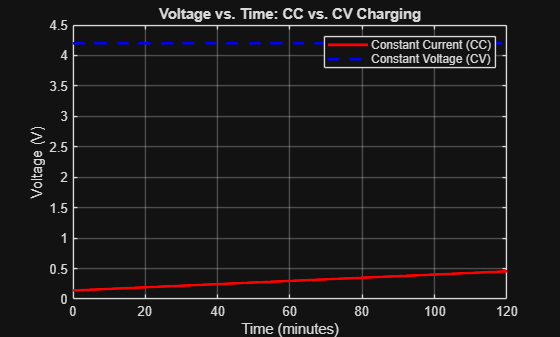

Vmax = 4.2;       
R = 0.07;        
RC = 3200;      
C = RC / R;      
I_const = 2;      
T_end = 7200;    
t = linspace(0, T_end, 1000); 

V_target = 0.99 * Vmax;

V_CC = I_const * R + (I_const / C) * t;
V_CC(V_CC > Vmax) = Vmax;
I_CC = I_const * ones(size(t));

t_CC_end = min(C * (V_target - I_const * R) / I_const, T_end);

E_CC = integral(@(t) I_const .* (I_const * R + I_const * t / C), 0, t_CC_end);

I_CV = @(t) (Vmax / R) * exp(-t / (R * C));
V_CV = Vmax * ones(size(t));

I_threshold = 0.05;  
t_CV_end = -log(I_threshold * R / Vmax) * (R * C);
t_CV_end = min(t_CV_end, T_end); 

E_CV = integral(@(t) Vmax .* I_CV(t), 0, t_CV_end);

figure;
plot(t/60, V_CC, 'r', 'LineWidth', 2); hold on;
plot(t/60, V_CV, 'b--', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Voltage (V)');
title('Voltage vs. Time: CC vs. CV Charging');
legend('Constant Current (CC)', 'Constant Voltage (CV)');
grid on;

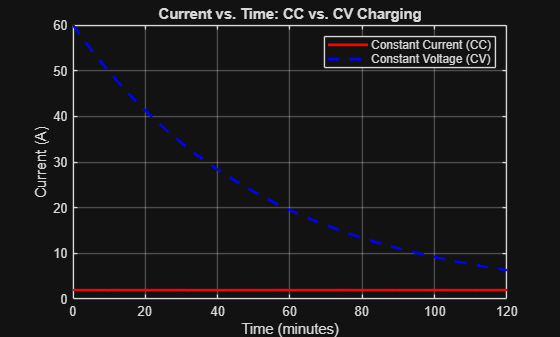


I_CV_vals = I_CV(t);
figure;
plot(t/60, I_CC, 'r', 'LineWidth', 2); hold on;
plot(t/60, I_CV_vals, 'b--', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Current (A)');
title('Current vs. Time: CC vs. CV Charging');
legend('Constant Current (CC)', 'Constant Voltage (CV)');
grid on;


fprintf('\nCharging Summary:\n');


Charging Summary:



fprintf('Constant Current (CC):\n');

Constant Current (CC):


fprintf('Charging Time: %.1f minutes\n', t_CC_end / 60);

Charging Time: 120.0 minutes


fprintf('Energy Delivered: %.2f J\n', E_CC);

Energy Delivered: 4284.00 J



fprintf('\nConstant Voltage (CV):\n');


Constant Voltage (CV):


fprintf('Charging Time (to %.2f A): %.1f minutes\n', I_threshold, t_CV_end / 60);

Charging Time (to 0.05 A): 120.0 minutes


fprintf('Energy Delivered: %.2f J\n', E_CV);

Energy Delivered: 721406.07 J
